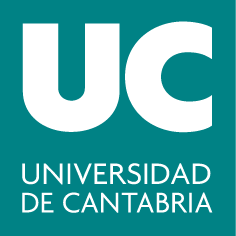

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Métodos Matemáticos en la Ingeniería**

**Bloque II: Métodos Numéricos**

# **1. Aritmética computacional**

## 1.1. Representación de los números

El ordenador, normalmente, recibe información en formato decimal, la cual es transformada a binario. Posteriormente, realiza las operaciones pertinentes, convierte el resultado de nuevo a decimal y finalmente informa al usuario de este resultado. La aritmética realizada en un ordenador involucra números con un número finito de dígitos, por lo que muchos cálculos se realizan con representaciones aproximadas de los números reales.

**Tipos de números en la computación:**

#### **Enteros (Integer)**

- Representados por un número fijo de bits, estos números no tienen parte fraccionaria.

- La aritmética de enteros es exacta, siempre y cuando el resultado no exceda el rango permitido.

Con 64 bits, por ejemplo, se pueden representar:

- **Enteros sin signo:** Desde 0 hasta $2^{64} -1$.

- **Enteros con signo:** Desde $-2^{63}$ hasta $2^{63} -1$.

#### **Números de punto flotante**

Para representar números con parte decimal, se utiliza la representación de punto flotante, que ofrece un rango más amplio de valores pero a costa de una menor precisión. La precisión de un cálculo depende del tipo de dato utilizado y del número de bits asignados para su representación.

Se representan de la forma: $(-1)^s \times m \times \beta^e$ donde 

- $$s$ --
$  Signo (0 para positivo, 1 para negativo);

- $m -$  Mantisa (o significando), se representa como $$0.a_1a_2a_3...$
$ en base $$\beta$
$, donde los dígitos $$a_i$$ cumplen $$0 \leq a_i \leq \beta - 1$$.

- $ $\beta$ --$  Base del sistema de numeración (generalmente 2 (sistema binario) en los ordenadores);

- $e -$ Exponente, un entero que indica la potencia a la que se eleva la base.

Notas importantes:

- Un sistema de números de punto flotante es** discreto y finito**. 

- Los números de punto flotante pueden representar un amplio rango de valores, desde números muy pequeños (cercanos a cero) hasta números muy grandes.

- La precisión de la representación depende de la longitud de la mantisa y del rango del exponente.

**Ejercicio:  ***Dado un sistema binario *$(\beta = 2)$* con una mantisa de 4 cifras. Representa los números 0.125,  0.5, 1, 1.125, 2.25.*

*Comprueba los resultados:*

Numbers = [0.125, 0.5, 1, 1.125, 2.25];   % números para representar
m = 4;                                    % 4 cifras de mantisa
float2bin(Numbers,m)                      % La definición de la función está al final del fichero

0.125 = (-1)^(0) * 0.1000 * 2^(-2)
0.500 = (-1)^(0) * 0.1000 * 2^(0)
1.000 = (-1)^(0) * 0.1000 * 2^(1)
1.125 = (-1)^(0) * 0.1001 * 2^(1)
2.250 = (-1)^(0) * 0.1001 * 2^(2)


Ir a "float2bin"

*Como podemos ver, la mantisa de los números 0.125, 0.5 y 1 es la misma: 0.1000, la diferencia está en el exponente. *

Si bien la mantisa de estos números comienza de la misma manera, la combinación de mantisa y exponente es lo que define el valor único de cada número en la representación de punto flotante.

#### Desbordamiento

La representación de números de punto flotante en un ordenador, aunque potente, tiene ciertas limitaciones inherentes que dan lugar a regiones excluidas en la recta numérica real.

**Las cinco regiones excluidas para los números de punto flotante son:**

- **Cero:** Debido a la normalización, el cero no puede ser representado como un número de punto flotante

- **Infinitamente pequeños (underflow):** Existen números reales extremadamente cercanos a cero que no pueden ser representados debido a las limitaciones de la mantisa y el exponente. Estos números se consideran "subnormales" o "denormalizados".

- **Infinitamente grandes (overflow):** Los números extremadamente grandes, tanto positivos como negativos, superan el rango máximo del exponente y se representan como infinito positivo o negativo.

- **NaN (Not a Number):** Esta categoría engloba resultados de operaciones indefinidas, como dividir cero entre cero o extraer la raíz cuadrada de un número negativo.

- **Huecos entre números representables:** Debido a la discretización de la recta real, existen "huecos" entre los números representables. Esto significa que hay valores reales que no pueden ser representados exactamente por un número de punto flotante.

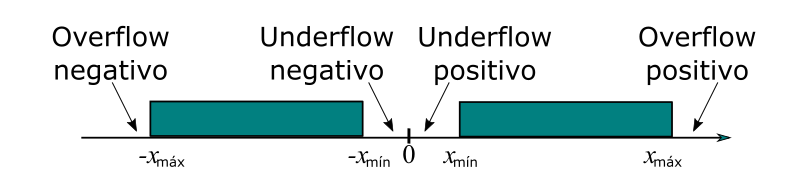

El **desbordamiento** (overflow en inglés) es una condición de error que ocurre cuando el resultado de una operación aritmética supera el rango máximo o mínimo representable para un determinado tipo de dato. En otras palabras, el número resultante es demasiado grande o demasiado pequeño para ser almacenado en la representación numérica asignada, lo que provoca una pérdida de información y, en consecuencia, un resultado incorrecto.

## 1.2. Estándar IEEE754

El estándar IEEE 754 es el estándar más utilizado para representar números de punto flotante en computación. Establecido en 1985 por el Instituto de Ingenieros Eléctricos y Electrónicos (IEEE), define formatos para diferentes precisiones de números de punto flotante, así como operaciones aritméticas y excepciones.**Estructura de un número de punto flotante según IEEE 754**

Un número de punto flotante según IEEE 754 se representa en tres campos:

- **Signo (S):** Un bit que indica si el número es positivo (0) o negativo (1).

- **Exponente (E):** Un campo de bits que representa el exponente del número.

- **Mantisa (M):** Un campo de bits que representa la parte fraccionaria del número.

**Formatos de punto flotante**

El estándar IEEE 754 define varios formatos de punto flotante, pero los más comunes son:

- **Simple precisión (32 bits):** Utiliza 1 bit para el signo, 8 bits para el exponente y 23 bits para la mantisa:

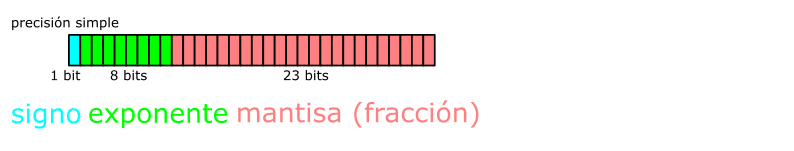

- **Doble precisión (64 bits):** Utiliza 1 bit para el signo, 11 bits para el exponente y 52 bits para la mantisa:

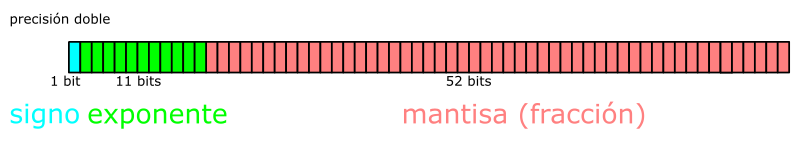

Para un número real dado $$$x = (-1)^s  \times m \times 2^e, \quad  1 < m < 2$$$, tenemos

- Signo: 0 - número positivo, 1 - negativo

- Exponente: $$$e = \lfloor \log_2 |x| \rfloor$$$(parte entera). Pongamos que se toman del total de $$n_e$ $bits en el  número, para el exponente. Con esos bits concretos, para considerar tanto exponentes negativos como positivos, al exponente $$e$ $se le suma $$2^{n_e-1}$$, de tal manera que el número  $$e_b$$, que se guarda como $$n_e$$ bits del exponente (en representación binaria) es:


$$$$ e_b = e +2^{n_e-1}- 1.$$$$


- Mantisa: $$m = 2^{-e}  |x|$$, Puesto que $$1 < m < 2$$, se guarda en la representación binaria la parte fraccionaria del $$m$$. 

**Ejercicio:  ***Codificar el número *$$\pi$$* en formato real de precisión simple.*

*Comprueba el resultado:*

float2single(pi); % La definición de la función está al final del fichero

3.141593 -> 0  10000000  10010010000111111011010


Ir a "float2single"

**Ejercicio (1.2):**

Escribir un script que transforma $x =- \pi$ al número de punto flotante (precisión simple).

x = -pi;





En la precisión simple, el número real de menor valor absoluto será: $$$x_{\min} = 0 \quad 00000001 \quad 0 \cdots 0$$$, o lo que es lo mismo  ($$e_b=1$, $e =1 - 127$$):


$$$$x_{\min} = 1 \cdot 2^{-126} \cdot 1 = 2^{-126} \approx  10^{-38}.$$$$


El número con mayor valor absoluto será: $$$x_{\max} = 0 \quad 11111110 \quad 1 \cdots 1$$$, o lo que es lo mismo ($$e_b = 2^8-1$, $e= 2^8-1-127 = 128$$):


$$
$$x_{\max} = 1 \cdot 2^{128} (1-2^{-24})\approx 10^{38}.$$$$


En MATLAB, existen comandos específicos para obtener los valores máximos y mínimos representables por números de punto flotante en diferentes precisiones. Estos comandos son útiles para entender los límites de las representaciones numéricas en cálculos de precisión simple (`single`) y precisión doble (`double`):

realmax_single = realmax('single')

realmax_single = single
3.4028e+38

realmin_single = realmin('single')

realmin_single = single
1.1755e-38

realmax_double = realmax % realmax('double')

realmax_double = 1.7977e+308

realmin_double = realmin % realmin('double')

realmin_double = 2.2251e-308

#### Números especiales

En MATLAB, además de los valores normalizados, también existen valores especiales que se utilizan para representar ciertos casos fuera del rango normal de valores de punto flotante. Estos valores incluyen los números subnormales, el infinito y el "Not a Number" (NaN).

1.  **Infinito (Inf)**

-     Representa valores que exceden el rango máximo representable. MATLAB utiliza `Inf` para estos casos.

-     Se obtiene cuando un cálculo produce un resultado mayor que el máximo valor representable:

Infinito = realmax * 1.1 % Incrementamos en un 10% el valor máximo representable

Infinito = Inf

2. **Not a Number (NaN)**

-     Representa resultados indefinidos o no representables, como ``0/0`` o ``Inf - Inf``, etc.

-     MATLAB utiliza ``NaN`` para estos casos.

N1 = 0 / 0

N1 = NaN

N2 = Inf / Inf

N2 = NaN

3. **Valores Denormalizados**

-     Son valores más pequeños que el mínimo valor normalizado (`realmin`), pero mayores que cero.

-     Los valores denormalizados permiten representar números muy pequeños con menos precisión.

valor_denormalizado = realmin / 2

valor_denormalizado = 1.1125e-308

4. **Cero**

- MATLAB maneja tanto el cero positivo (`+0`) como el cero negativo (`-0`). Aunque en la mayoría de las operaciones estos dos valores se comportan de manera idéntica, son distintos a nivel de representación binaria en punto flotante.

Representación binaria de los números especiales:

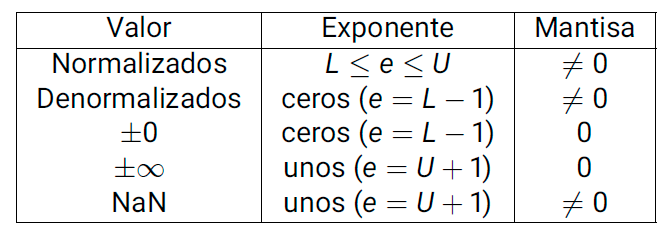

**Ejercicio 1.3: **El logaritmo natural corresponde a la función inversa de la función exponencial natural: 

	
$$$$x = \ln(\exp(x)) = \exp(\ln(x)).$$$$


	Muestra con un ejemplo que en aritmética computacional no es exactamente así.

% ... Escribe aquí el código :




#### Precisión de la maquina

La precisión de la máquina (también conocida como "**epsilon de la máquina**" o `eps`) es el valor más pequeño que, al sumarse a 1, produce un resultado distinto de 1.

**Ejercicio 1.4:** Usando la definición del epsilon de la maquina, escribe el código para obtener su valor:

% ... Escribe aquí el código para obtener el valor de epsilon de la máquina:







Compara el resultado con el valor predefinido de MATLAB:

eps

ans = 2.2204e-16

## 1.3. Análisis del error

En la práctica del cálculo numérico, es crucial reconocer que las soluciones calculadas por el computador no son soluciones matemáticas exactas. La precisión de una solución numérica puede verse disminuida por diversos factores, algunos de naturaleza sutil. Comprender estas dificultades es esencial para desarrollar algoritmos numéricos adecuados y mejorar su precisión y estabilidad.

#### Tipos de errores

Supongamos que $\hat{p}$ es una aproximación a $p$. 

- El **error absoluto** de la aproximación es $E_p = |p-\hat{p}|$

- El **error relativo** es $R_p = \frac{|p-\hat{p}|}{p}$  (El error relativo también se puede multiplicar por $$100\%$$.)

- Diremos que un número $\hat{p}$ es una aproximación a $p$ con $d$ **cifras decimales significativas** si $d$ es el mayor número natural tal que


$$\frac{|p - \hat{p}|}{|p|} < \frac{10^{-d}}{2}$$


Ejemplo: Determinar el número de cifras significativas de las siguientes aproximaciones:

- 
$$x = 3.141592,   \quad  \hat{x} = 3.14$$


- 
$$y = 1\,000\,000,\quad \hat{y} = 999\, 996$$


- 
$$z = 0.000012, \quad \hat{z} = 0.000009$$


% escribe aquí el código para determinar el número de cifras significativas:




Para comprobar el resultado:

x = [3.141592, 1000000, 0.000012]; 
xa = [3.14, 999996, 0.000009];
cifras(x,xa);   % La definición de la función está al final del fichero

x = 3.141592, x_aprox = 3.140000:  Es una aproximación con 2 cifras significativas
x = 1000000.000000, x_aprox = 999996.000000:  Es una aproximación con 5 cifras significativas
x = 0.000012, x_aprox = 0.000009:  Es una aproximación con 0 cifras significativas


Ir a "cifras"

**Factores que afectan la precisión numérica:**

- **Errores de Redondeo**: Los computadores representan números con una precisión finita, lo que lleva a errores de redondeo. La política de redondeo implícitamente contemplada en el estándar IEEE754 es el **redondeo al más próximo. **El error relativo máximo cometido al redondeo de un número es la mitad del epsilon de la maquina y se llama la unidad de redondeo: $\mathbf{u} = \varepsilon_M/2$.

- **Errores de Truncamiento**: Ocurren cuando se utilizan aproximaciones en lugar de valores exactos, como en la discretización de ecuaciones diferenciales o la sustitución de una función por un uno de sus polinomios de Taylor. 

- **Estabilidad del Algoritmo**: Un algoritmo numérico estable es aquel que no amplifica los errores de redondeo durante sus cálculos. Un proceso numérico es  inestable cuando no es estable. Un mismo algoritmo puede ser estable para algunos datos iniciales e inestable para otros. Entonces se dice que el algoritmo es condicionalmente estable.

- **Condicionamiento del Problema**: Algunos problemas son inherentemente sensibles a pequeñas perturbaciones en los datos de entrada. Estos problemas se consideran mal condicionados, y los errores de entrada pueden amplificarse significativamente en el resultado.

**Ejercicio 1.5: **Sea $$\mu = \epsilon_M/2$$, donde $$\epsilon_M$$ representa la precisión de la máquina en el estándar IEEE de precisión doble. Se realizan las siguientes operaciones en una máquina que opera bajo dicho estándar:

-  
$$$1+\mu-1$$$


- 
$$$-1 +\mu +1$$$


- 
$$(1+2\mu)+\mu-1$$


- 
$$(1 + 2\mu) + \mu - (1 + 2\mu)$$


	Ejecútalas y explica los resultados.

% Escribe aquí el código:




#### **Pérdida de cifras significativas**

La pérdida de cifras significativas se produce cuando operaciones matemáticas reducen la precisión del resultado final al eliminar dígitos significativos. Este fenómeno puede ocurrir, por ejemplo, durante la resta de números similares:

%Consideremos los números:
format long
a1=0.3333333333333298

a1 =    0.333333333333330


a2=0.3333333333333187

a2 =    0.333333333333319


En los valores mostrados, las últimas cifras significativas de `a1` y `a2` han sido redondeadas:

- Las cifras `298` del número `a1` han sido redondeadas a `300`, lo cual introduce un error en la decimocuarta cifra decimal.

- Las cifras `187` del número `a2` han sido redondeadas a `190`, lo cual introduce un error en la decimoquinta cifra decimal.

*Resta Exacta:* Si restamos manualmente los valores exactos de `a1` y `a2`, el resultado debería ser: $0.3333333333333298-0.3333333333333187=1.11\times 10-14$

*Resta en MATLAB:  *

resultado = a1 - a2

resultado =      1.110223024625157e-14


Observe cómo MATLAB proporciona un valor cuya quinta cifra significativa es errónea debido a la cancelación sustractiva. Hemos pasado de errores en la decimocuarta y decimoquinta cifras a un error significativo en la quinta cifra del resultado. Esto muestra cómo los errores de redondeo pueden amplificarse drásticamente cuando restamos números muy cercanos.

**Estrategias para mitigar la pérdida de cifras significativas**

- Reformular el problema para evitar operaciones que conduzcan a cancelaciones sustractivas.

- Utilizar representaciones de mayor precisión, como la precisión múltiple (`vpa` en MATLAB con el Symbolic Math Toolbox), para reducir los errores de redondeo.

**Ejercicios:**

**1.6:**  Reformular expresiones para que su evaluación sea numéricamente estable.

- 
$$$\frac{1}{1+2x} - \frac{1-x}{1+x}$ para $|x|\ll 1$$$


- 
$$$\sqrt{x+ \frac{1}{x}} - \sqrt{x- \frac{1}{x}}$ para $|x|\gg 1$$$


% Escribe aquí el código:


**1.7:  **Dada la función

	
$$$$f(x) = \frac{1}{1-x} - \frac{1}{1+x}, \quad |x|\neq 1.$$$$


	¿Para qué valores de $$x$$ es difícil calcular precisamente la expresión en aritmética de punto flotante? Reformular la expresión de manera que su evaluación numérica sea estable.

% Escribe aquí el código:


**1.8:** Para calcular el punto medio $$m$ $de un intervalo $$[a,b]$$,  ¿cuál de las siguientes expresiones es preferible en aritmética de punto flotante? ¿Cuándo? ¿Por qué? 

-  
$$$m = \frac{a+b}{2.0}$$$


- 
$$$m = a + \frac{b-a}{2.0}$$$


% Escribe aquí el código:


**La fórmula mejorada para la resolución de la ecuación cuadrática**

Dada la ecuación cuadrática $ $ax^2 + bx+c =0$ $con raíces $x_{1,2} = \frac{-b \pm \sqrt{b^2-4ac}}{2a}.
$

Si $$b^2 \gg ac$, $\sqrt{b^2-4ac} \approx |b|$ $\rightarrow$$  Cancelación en una de las raíces.

 ¿Cómo evitar la cancelación?

Multiplicar numerador y denominador  de la raíz "problemática" por $$-b-\sqrt{b^2-4ac} $$:


$$
x_{1,2} = \frac{2c}{-b\mp\sqrt{b^2-4ac}}.$$


En resumen, 

- Si $$b>0$$: $
x_{1} = \frac{-2c}{b+\sqrt{b^2-4ac}}, \quad$ $x_{2} = \frac{-b - \sqrt{b^2-4ac}}{2a}.$

- Si $$b<0$$:  $x_{1} = \frac{-b +\sqrt{b^2-4ac}}{2a},\quad $$
x_{2} = \frac{-2c}{b-\sqrt{b^2-4ac}}.$

**Ejercicio**: usa la fórmula adecuada para calcular las raíces de las siguientes ecuaciones:

- 
$$x^2 - 1\,000.001x + 1 = 0$$


- 
$$x^2 - 10\,000.0001x + 1 = 0$$


- 
$$x^2 - 100\,000.00001x + 1 = 0$$


**Ejercicio 1.10**: Usa los resultados anteriores para construir un algoritmo que calcule las raíces de una ecuación cuadrática en todas las situaciones posibles, incluyendo los casos problemáticos cuando $$\sqrt{b^2-4ac} \approx |b|$$.

% Escribe aquí el código:





#### Orden de aproximación

Se dice que una función $f(h)$ es de orden $g(h)$ cuando $h\to 0$, lo que se denota por $f(h) = \mathbf{O}(g(h))$ (O mayúscula de Landau), si existen constantes $C$ y $c$ tales que


$$|f(h)| \leq C| g(h)|, \quad |h|\leq c.$$


La notación $\mathbf{O}(\cdot)$ proporciona una forma muy útil de describir la velocidad de crecimiento (o decrecimiento) de una función en terminos de velocidad de crecimiento (o decrecimiento) de funciones elementales bien conocidas.

Supongamos que una función $p(h)$ aproxima a otra $f(h)
$ y que existen una constante $M$y un número natural $n$ tales que

$\frac{|f(h) - p(h)|}{|h^n|}\leq M$ para $h$ suficientemente pequeño.

Entonces, se dice que $p(h)$ aproxima a $f(h)$ con orden de aproximación $\mathbf{O}(h^n)$: $f(h) = p(h) + \mathbf{O}(h^n)$.

#### Análisis de la propagación del error

 La representación en coma flotante mediante redondeo viene dada por $fl(x) = x(1+\epsilon), \quad \text{siendo  } \left| \epsilon \right|  \leq \mathbf{u}.$

El error relativo del número de  punto flotante: $$$\frac{|x- fl(x)|}{|x|} = \frac{|x-(x+x\epsilon)|}{|x|} = |\epsilon|.$$$

Se tiene representaciones de punto flotante$ $fl(x)$$ y $$fl(y)$$ para los números reales $$x$$ e $$y$$. Y que los símbolos  $\oplus,\; \ominus,\; \otimes,\; \oslash$ $ representan las operaciones de suma, resta, multiplicación y división de la máquina, respectivamente:


$$x \oplus y  = fl(fl(x) + fl(y));\\
x \ominus y = fl(fl(x) - fl(y));\\
x \otimes y = fl(fl(x) \cdot fl(y));\\
x \oslash y = fl(fl(x)/fl(y)).
$$


Consideramos la suma: $$x \oplus y  = fl(fl(x) + fl(y)$$. Según la definición de punto flotante tenemos:


$$$$x \oplus y  = (x(1+\epsilon_x) + y(1+\epsilon_y))(1+\epsilon_{x+y}).$$$$


Elegimos $$\epsilon= \max (|\epsilon_x|, |\epsilon_y|, |\epsilon_{x+y}|)< \mathbf{u}$$:


$$
$$x \oplus y  = (x + y)(1+\epsilon_{x+y})^2 = (x+y) (1+2\epsilon + \epsilon^2).$$$$


- Error relativo de la suma:  $\frac{|(x+y) - (x \oplus y)|}{|x+y|} \leq \frac{|x| + |y|}{|x+y|}(2\epsilon+\epsilon^2) \simeq \frac{|x| + |y|}{|x+y|}\cdot 2 \epsilon \leq \frac{|x| + |y|}{|x+y|}\varepsilon_M$

En misma manera se puede calcular los errores de otras operaciones aritméticas:

- Error del producto: $
$$\frac{|xy- fl(fl(x) \cdot fl(y))|}{|xy|} \leq 3 \epsilon + 3\epsilon^2 + \epsilon^3 \simeq 3 \epsilon \leq 2 \varepsilon_M$$$

- Error de la división:  $$$\frac{|x/y- fl(fl(x) / fl(y))|}{|x/y|} \leq \frac{3 \epsilon + \epsilon^2}{1- \epsilon} \simeq  3 \epsilon \leq 2\varepsilon_M$$$

- Error (absoluto) en una función: $$$\Delta f(\hat{x}) = |f(x) - f(\hat{x})| \cong |f'(\hat{x})|\Delta \hat{x}$$$

**Ejemplo: **Dado un valor de$ $\hat{x} = 2.5$ $con un error $$\Delta \hat{x} = 0.01$$, estima el error resultante en la función $$f(x) = x^3$$.

Valor verdadero: $$f(2.5) = 15.625$$, 


$$$\Delta f(\hat{x}) = |f'(\hat{x})|\Delta \hat{x} = 3 \cdot 2.5^2 \cdot 0.01 = 0.1875$
$$


Ya que el valor verdadero se encuentra entre $$15.4375$ y $15.8125$$. 

De hecho,  $$f(2.49) =  15.4382$, $f(2.51) =15.8132 $$

En los cálculos numéricos, es común que los errores iniciales en los datos se propaguen a lo largo de una cadena de operaciones. Una cualidad deseable de cualquier proceso numérico es que un pequeño error en las condiciones iniciales produzca solo pequeños errores en el resultado final. Un algoritmo que posee esta cualidad se denomina **estable**. Por el contrario, un algoritmo es **inestable** si amplifica los errores iniciales, resultando en grandes errores en el resultado final.

- El producto  $$\otimes$ $ de dos números de máquina es un cálculo estable, sólo se pueden producir errores de desbordamiento (overflow)

a = 1e308; % Cerca del límite superior para double
b = 2;
result = a * b % Esto puede causar overflow

result =    Inf


- La división $ $\oslash$$ de dos números de máquina es un cálculo estable, pueden ocurrir errores de desbordamiento (overflow) y subdesbordamiento (underflow) si el resultado es demasiado grande o demasiado pequeño para ser representado.

a = 1e308; % Cerca del límite superior para double
b = 2;
result = a / b % Esto es estable y no causa overflow

result =     5.000000000000000e+307


c = 0.1;
result2 = a / c

result2 =    Inf


- La suma$ $\oplus$$ de dos números de máquina es estable cuando los dos números tienen el mismo signo, y puede ser inestable cuando los dos números tienen signo distinto (cancelación de cifras significativas).

Las manipulaciones en cálculos numéricos con números de punto flotante pueden ser especialmente propensas a errores de redondeo. A continuación se presentan algunas de las situaciones más comunes y cómo estos errores pueden afectar los resultados.

1. **Suma de Números con Diferentes Exponentes**

Cuando se suman dos números de punto flotante, el número con el exponente menor se modifica para que los exponentes sean iguales. Esta modificación puede llevar a una pérdida significativa de precisión en el número de menor exponente.

% Compara:
a = 10^50 + 812 -10^50 + 10^35 + 511 -10^35;
% La misma suma, pero con los términos reordenados:
a1 = 10^50 -10^50 + 10^35 -10^35 + 511 + 812 ;
fprintf("a = %d, \t a1 = %d\n",a,a1)

a = 0, 	 a1 = 1323


2. **Cálculos grandes**

En procesos que involucran un gran número de cálculos, aunque el error de redondeo individual sea pequeño, el efecto acumulativo puede ser significativo.

3. **Cancelación por resta**

La resta de dos números de punto flotante casi iguales puede resultar en la cancelación de los dígitos significativos, llevando a una pérdida significativa de precisión.

4. **Evaluación de **$\( e^x \)$** usando Series Infinitas**

La evaluación de funciones como $\( e^x \)$ usando series infinitas puede ser propensa a errores de redondeo. Los términos de la serie pueden volverse muy grandes antes de reducirse, acumulando errores de redondeo significativos.

**Ejercicio 1.10: **Se puede calcular $$e^{x}$$ utilizando el desarrollo en serie de la función exponencial:

	
$$$$e^x = \sum_{n=0}^{\infty} \frac{x^n}{n!}$$$$


-  Sumar los 100 primeros términos de la serie para calcular$ $e^{-30}$$.

-  Comparar con `exp(-30)`. Explicar los resultados. 

-  Escrbir un algoritmo para obtener la estimación más precisa. 

% Calculamos exp(-30) usando series:
x = -30;
    s = 1;
    for i=1:50 
        s = s + x^i/factorial(i);
    end
fprintf("Series: %.4e, Valor correcto: %.4e", s, exp(-30))

Series: 8.7823e+08, Valor correcto: 9.3576e-14

Para valores negativos grandes, como $e^{-30}$, es preferible calcularlo como $\frac{1}{e^{30}}$, ya que la serie para $e^{30}$ converge más rápidamente y con menos errores de redondeo:

x = 30;
    s = 1;
    for i=1:50 
        s = s + x^i/factorial(i);
    end
s2 = 1/s

s2 =      9.360412493278424e-14


Ahora podemos escribir el algoritmo completo:

% Escribe aquí el código:







## Bibliografía

- [Chapra S.C.; Canale R. (2015) Métodos Numéricos para Ingenieros. Ed. McGRaw-Hill](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=436963) (Capítulo 3)

- [Mathews J.H., Fink K.D. (2000) Métodos Numéricos con MATLAB. Ed. Prentice Hall](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=163396) (Capítulo 1)

- [Goldberg D., What Every Computer Scientist Should Know About Floating-Point Arithmetic](https://docs.oracle.com/cd/E19957-01/806-3568/ncg_goldberg.html)

Funciones auxiliares

1. Función que transforma un numero (o un vector de números) al sistema binario con m cifras en la mantisa

function[] = float2bin(Numbers,m)
for num = Numbers
    sign_bit = num2str(num<0); %bit de signo (1 si x es negativo)

    % Parte entera y fraccionaria
    integer_part = floor(num);
    fractional_part = num - integer_part;

    % Convertir la parte entera a binario
    bin_integer_part = dec2bin(integer_part);

    % Convertir la parte fraccionaria a binario con 4 cifras de mantisa
    bin_fractional_part = repelem('0',2*m);
    fraction = fractional_part;
    for i3 = 1:2*m
        fraction = fraction * 2;
        if fraction >= 1
            bin_fractional_part(i3) = '1';
            fraction = fraction - 1;
        else
            bin_fractional_part(i3) = '0';
        end
    end

    % Normalizar la mantisa y calcular el exponente
    if integer_part > 0
        exponent =  fix(log2(num))+1;
        mantissa = [bin_integer_part bin_fractional_part(1:m-length(bin_integer_part))];
    else
        leading_zeros = find(bin_fractional_part == '1', 1) - 1;
        exponent = -leading_zeros;
        mantissa = bin_fractional_part((leading_zeros + 1):(leading_zeros + m));
    end

    fprintf('%.3f = (-1)^(%s) * 0.%s * 2^(%d)\n', num, sign_bit, mantissa, exponent);
end
end

2. Función que transofrma un número dado al sistema binario de precisión simple (32 bits)

function [sign, exponent, mantissa] = float2single(x2)
% Signo:
sign = num2str((x2<0));
% Exponente:
e = fix(log2(x2));
eg = e-1 + 2^7;
exponent = dec2bin(eg,8);
%Mantissa:
integer_part2 = floor(x2);
bin_integer_part2 = dec2bin(integer_part2);
fractional_part2 = x2 - integer_part2;
fraction2 = fractional_part2;
m3= 23;
bin_fractional_part2 = repelem('0',2*m3);
for i2 = 1:2*m3
    fraction2 = fraction2 * 2;
    if fraction2 >= 1
        bin_fractional_part2(i2) = '1';
        fraction2 = fraction2 - 1;
    else
        bin_fractional_part2(i2) = '0';
    end
end
if integer_part2 > 0
    mantissa = [bin_integer_part2 bin_fractional_part2(1:m3-length(bin_integer_part2)+1)];
else
    leading_zeros2 = find(bin_fractional_part2 == '1', 1) - 1;
    mantissa = bin_fractional_part2((leading_zeros2 + 1):(leading_zeros2 + m3+1));
end

mantissa =  mantissa(2:24);
fprintf("%f -> %s  %s  %s\n",x2,sign, exponent, mantissa)
end

3. Función que determina el número de cifras significativas de la aproximación dada:

function [d] = cifras(x,xa)
n = length(x);
for k = 1:n
    d = fix(log10(0.5*abs(x(k))/abs(x(k) - xa(k))));
    fprintf("x = %f, x_aprox = %f:  Es una aproximación con %d cifras significativas\n",x(k),xa(k),d);
end
end